### Nuñez Peralta Yanet

## Tarea 4

## Problema 1 Libro Burden.

Mediante el método de Newton con $x_0 =0$ calcule $x_n$ para el siguiente sistema no lineal

### d)

 
$$\begin{array}{l}
x^2 +y-37=0\\
x-y^2 -5=0\\
x+y+z-3=0
\end{array}$$


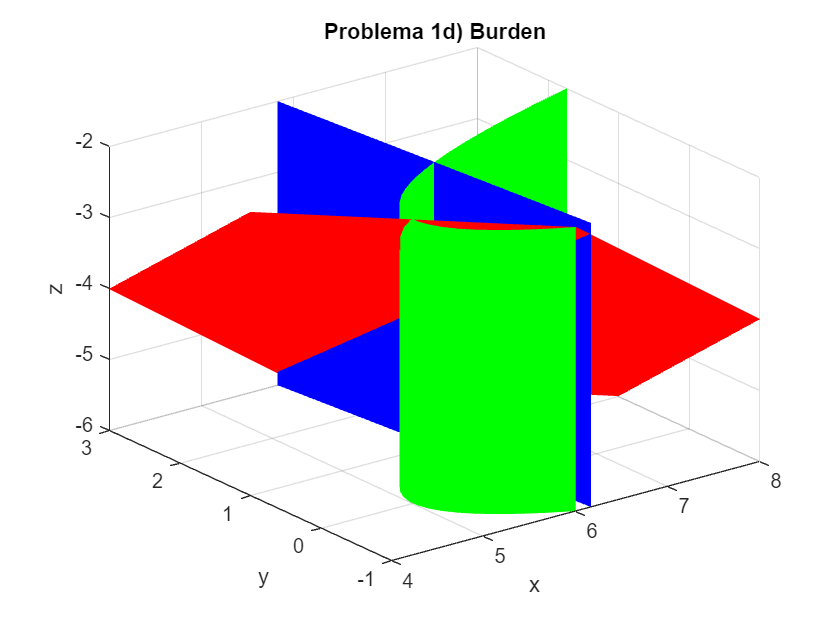

syms x y z;

ec1=@(x,y,z)x.^2+y-37;
ec2=@(x,y,z)x-y.^2-5;
ec3=@(x,y,z)x+y+z-3;

fimplicit3(ec1,[4 8 -1 3 -6 -2],'EdgeColor','none','facecolor','b');
hold on
fimplicit3(ec2,[4 8 -1 3 -6 -2],'EdgeColor','none','facecolor','g');
fimplicit3(ec3,[4 8 -1 3 -6 -2],'EdgeColor','none','facecolor','r');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 1d) Burden')

eq1=x^2+y-37;
eq2=x-y^2-5;
eq3=x+y+z-3;

F_42=[eq1 eq2 eq3];
X0=[6.1 1.5 -3.5];

[E_1d,Sol_1d,err_1d]=Newton_Multivariable(F_42,X0,5,1e-6)

E_1d = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_1d =      6
     1
    -4


err_1d = 1.1343e-11

## Problema 2 Libro Burden

Use las opciones de graficaión para aproximar las soluciones de los siguientes problemas de sistema de ecuaciones no lineales.

### a) 


$$\begin{array}{l}
x\left(1-x\right)+4y=12\\
{\left(x-2\right)}^2 +{\left(2y-3\right)}^2 =25
\end{array}$$


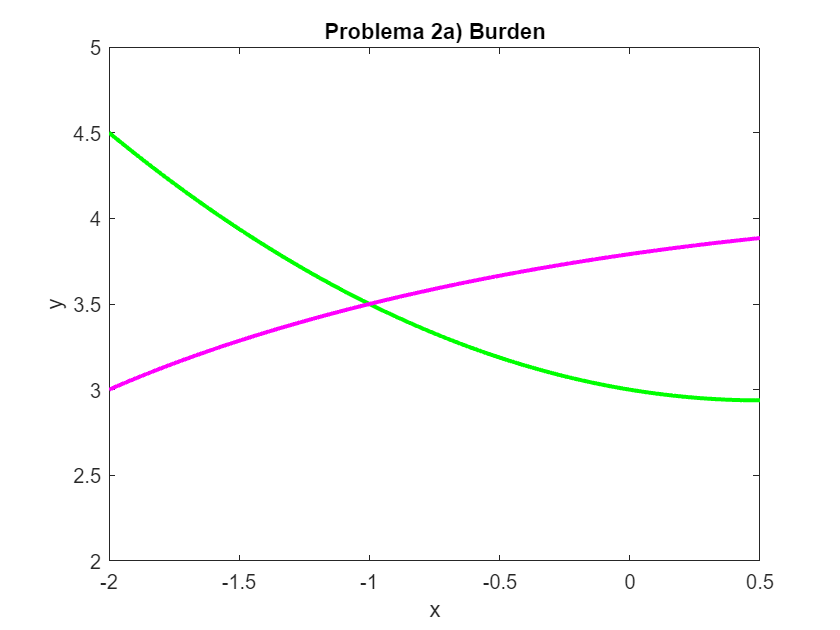

syms x y;

ec1=@(x,y)x.*(1-x)+4*y-12;
ec2=@(x,y)(x-2).^2+(2*y-3).^2-25;

fimplicit(ec1,[-2 0.5 2 5],'-g','LineWidth',2);
hold on
fimplicit(ec2,[-2 0.5 2 5],'-m','LineWidth',2);
hold off
xlabel('x');
ylabel('y');
title('Problema 2a) Burden')

eq1=x*(1-x)+4*y-12;
eq2=(x-2)^2+(2*y-3)^2-25;

F_2a=[eq1 eq2];
X0=[-1.1 3.4];

[E_2a,X_2a,err_2a]=Newton_Multivariable(F_2a,X0,15,1e-6)

E_2a = 'La aproximacion esta dentro de la tolerancia indicada'

X_2a =    -1.0000
    3.5000


err_2a = 1.2919e-11

### d)


$$\begin{array}{l}
10x-2y^2 +y-2z-5=0\\
8y^2 +4z^2 -9=0\\
8\textrm{yz}+4=0
\end{array}$$


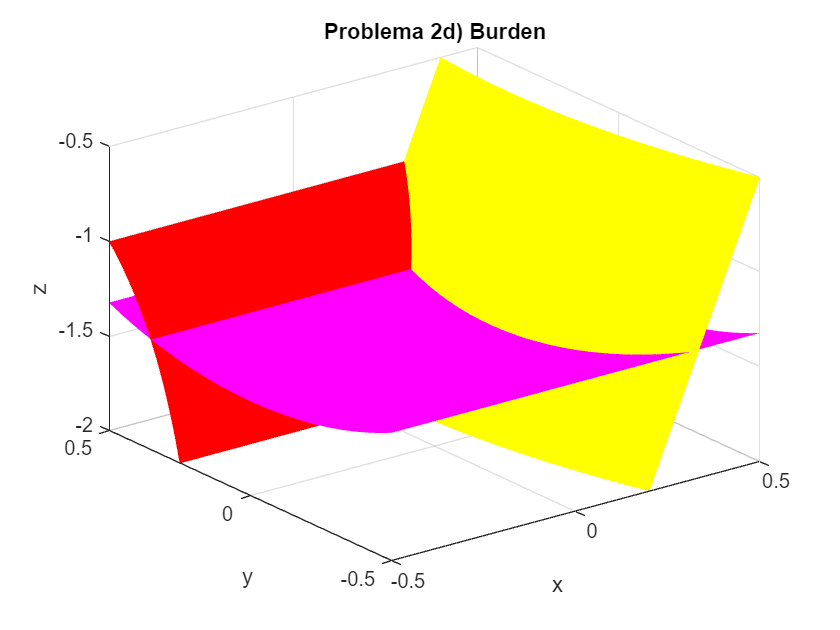

syms x y z;

ec1=@(x,y,z)10*x-2*y.^2+y-2*z-5;
ec2=@(x,y,z)8*y.^2+4*z.^2-9;
ec3=@(x,y,z)8*y.*z+4;

fimplicit3(ec1,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','y','EdgeColor','none');
hold on
fimplicit3(ec2,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','m','EdgeColor','none');
fimplicit3(ec3,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','r','EdgeColor','none');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 2d) Burden')

eq1=10*x-2*y^2+y-2*z-5;
eq2=8*y^2+4*z^2-9;
eq3=8*y*z+4;

F_2aB=[eq1 eq2 eq3];
X0=[0 0 -1];

[E_2aB,Sol_2aB,err_2aB]=Newton_Multivariable(F_2aB,X0,5,1e-6)

E_2aB = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_2aB =     0.2068
    0.3536
   -1.4142


err_2aB = 2.1511e-08

## Problema 4 Libro Burden.

Aplique el método de Newton-Multivariable para aproximar las soluciones a los siguientes sistemas no lineales. Itere hasta que $\left|\right|x^k -x^{k-1} \left|\right|<{10}^{-6}$.

### a)

 
$$\begin{array}{l}
x\left(1-x\right)+4y=12\\
{\left(x-2\right)}^2 +{\left(2y-3\right)}^2 =25
\end{array}$$


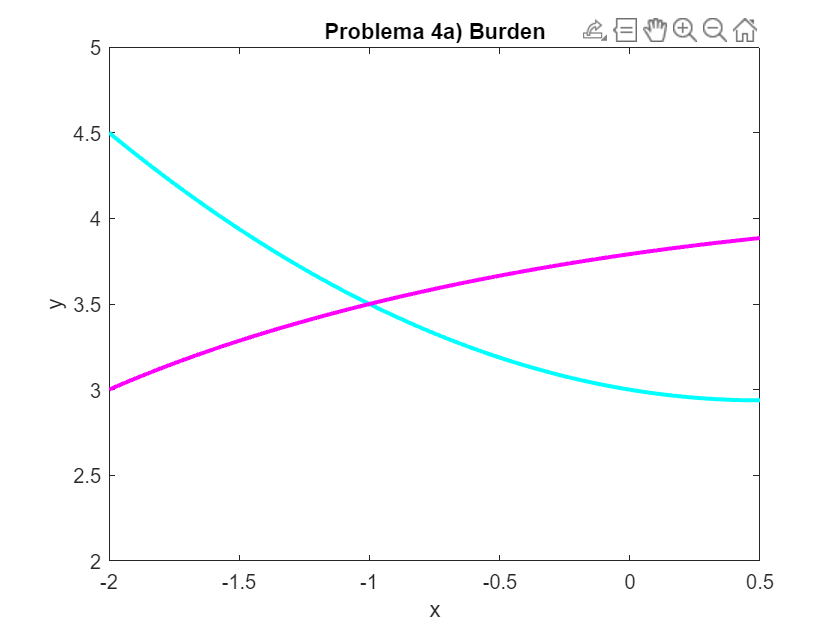

syms x y;

ec1=@(x,y)x.*(1-x)+4*y-12;
ec2=@(x,y)(x-2).^2+(2*y-3).^2-25;

fimplicit(ec1,[-2 0.5 2 5],'-c','LineWidth',2);
hold on
fimplicit(ec2,[-2 0.5 2 5],'-m','LineWidth',2);
hold off
xlabel('x');
ylabel('y');
title('Problema 4a) Burden')

eq1=x*(1-x)+4*y-12;
eq2=(x-2)^2+(2*y-3)^2-25;

F_4a=[eq1 eq2];
X0=[-1.1 3.4];

[E_4a,Sol_4a,err_4a]=Newton_Multivariable(F_4a,X0,15,1e-6)

E_4a = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_4a =    -1.0000
    3.5000


err_4a = 1.2919e-11

### b)

 
$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;5x^2 -y^2 =0\\
y-0\ldotp 25\left(\sin \left(x\right)+\cos \left(y\right)\right)=0
\end{array}$$


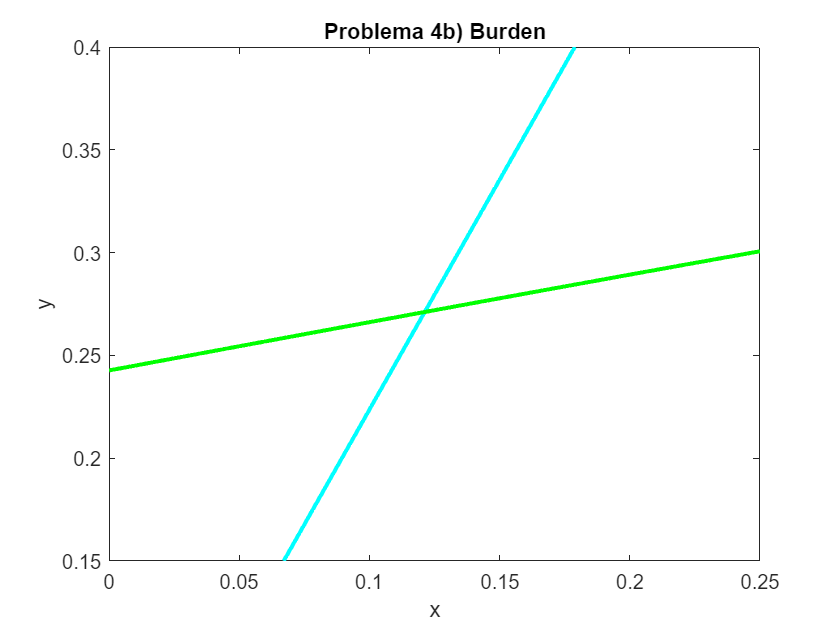

syms x y;

ec1=@(x,y)5*x.^2-y.^2;
ec2=@(x,y)y-0.25*(sin(x)+cos(y));

fimplicit(ec1,[0 0.25 0.15 0.4],'-c','LineWidth',2);
hold on
fimplicit(ec2,[0 0.25 0.15 0.4],'-g','LineWidth',2);
hold off
xlabel('x');
ylabel('y');
title('Problema 4b) Burden')

eq1=5*x^2-y^2;
eq2=y-0.25*(sin(x)+cos(y));

F_42=[eq1 eq2];
X0=[0.1 0.2];

[E_4b,Sol_4b,err_4b]=Newton_Multivariable(F_42,X0,5,1e-6)

E_4b = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_4b =     0.1212
    0.2711


err_4b = 6.7432e-09

### c) 


$$\begin{array}{l}
15x+y^2 -4z=13\\
\;\;\;x^2 +10y-z=11\\
\;\;\;\;\;\;\;y^3 -25z=-22
\end{array}$$


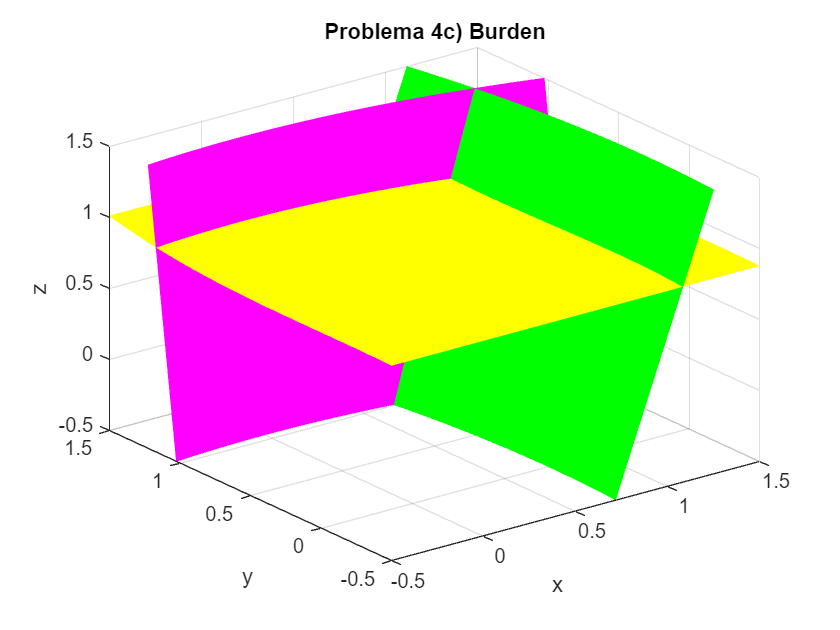

syms x y z;

ec1=@(x,y,z)15*x+y.^2-4*z-13;
ec2=@(x,y,z)x.^2+10*y-z-11;
ec3=@(x,y,z)y.^3-25*z+22;

fimplicit3(ec1,[-0.5 1.5],'facecolor','g','EdgeColor','none');
hold on
fimplicit3(ec2,[-0.5 1.5],'facecolor','m','EdgeColor','none');
fimplicit3(ec3,[-0.5 1.5],'facecolor','y','EdgeColor','none');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 4c) Burden')

eq1=15*x+y^2-4*z-13;
eq2=x^2+10*y-z-11;
eq3=y^3-25*z+22;

F_42=[eq1 eq2 eq3];
X0=[1 1 9];

[E_4c,Sol_4c,err_4c]=Newton_Multivariable(F_42,X0,5,1e-6)

E_4c = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_4c =     1.0364
    1.0857
    0.9312


err_4c = 6.5182e-09

### d)

 
$$\begin{array}{l}
10x-2y^2 +y-2z-5=0\\
8y^2 +4z^2 -9=0\\
8\textrm{yz}+4=0
\end{array}$$


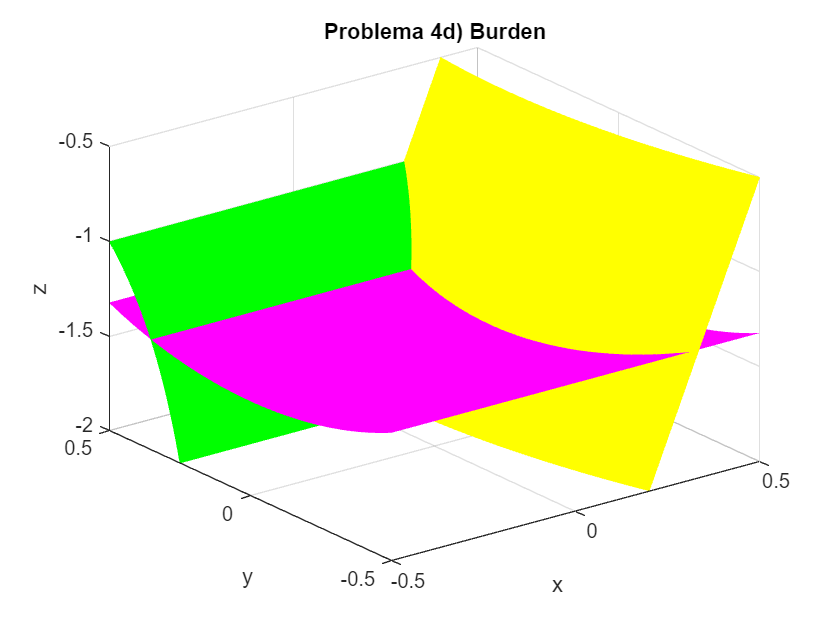

syms x y z;

ec1=@(x,y,z)10*x-2*y.^2+y-2*z-5;
ec2=@(x,y,z)8*y.^2+4*z.^2-9;
ec3=@(x,y,z)8*y.*z+4;

fimplicit3(ec1,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','y','EdgeColor','none');
hold on
fimplicit3(ec2,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','m','EdgeColor','none');
fimplicit3(ec3,[-0.5 0.5 -0.5 0.5 -2 -0.5],'facecolor','g','EdgeColor','none');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 4d) Burden')

eq1=10*x-2*y^2+y-2*z-5;
eq2=8*y^2+4*z^2-9;
eq3=8*y*z+4;

F_42=[eq1 eq2 eq3];
X0=[0 0.5 -1.5];

[E_4d,Sol_4d,err_4d]=Newton_Multivariable(F_42,X0,5,1e-6)

E_4d = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_4d =     0.2068
    0.3536
   -1.4142


err_4d = 1.9418e-09

La solución al sistema de ecuaciones no lineales es:


$$\begin{array}{l}
x=\;\;\;0\ldotp 206801948466054\\
y=\;\;\;0\ldotp 353553390593274\\
z=-1\ldotp 414213562373095
\end{array}$$


## Problema 4.2 Libro Nieves

Resuelva el siguiente sistema


$$\begin{array}{l}
{\textrm{Ec}}_1 :\;\;{\;\;x}_1 x_2 +x_6 x_4 =18\\
{\textrm{Ec}}_2 :\;\;x_2 +x_5 +x_6 =12\\
{\textrm{Ec}}_3 :\;\;x_1 +\textrm{Ln}\left(\frac{x_2 }{x_4 }\right)=3\\
{\textrm{Ec}}_4 :\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_3^2 +x_3 =2\\
{\textrm{Ec}}_5 :\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_2 +x_4 =4\\
{\textrm{Ec}}_6 :\;\;\;\;\;\;\;\;x_3 \left(x_3 +6\right)=7
\end{array}$$


Utilizando las sugerencias dadas (reducción, partición, entre otras).

- Podemos reducir el sistema de ecuaciones suponiendo que $x_3 =1$, lo cual cumple para las restriciones de la ecuación 4 y 6, las cuales tienen como raíz en comun "1"


$$\begin{array}{l}
{\textrm{Ec}}_4 :\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_3^2 +x_3 ={\left(1\right)}^2 +1=2\\
{\textrm{Ec}}_6 :\;\;\;\;\;\;\;\;x_3 \left(x_3 +6\right)=\left(1\right)\left(1+6\right)=7
\end{array}$$


             Con lo cual nuestro siguiente sistema queda como:


$$\begin{array}{l}
{\textrm{Ec}}_1 :\;\;{\;\;x}_1 x_2 +x_6 x_4 =18\\
{\textrm{Ec}}_2 :\;\;x_2 +x_5 +x_6 =12\\
{\textrm{Ec}}_3 :\;\;x_1 +\textrm{Ln}\left(\frac{x_2 }{x_4 }\right)=3\\
{\textrm{Ec}}_5 :\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_2 +x_4 =4
\end{array}$$


          2.  A partir de la ecuación 5 podemos despejar alguna de sus incognitas ($x_2 \;o\;x_4$) para poder sustiur en las ecuaciones 1, 3 y/o 2, de esta forma:


$${\textrm{Ec}}_5 :x_2 +x_4 =4\;\;\cdots x_4 =4-x_2$$


               Sustituyendo y reacomodando las ecuaciones se obtiene:


$$\begin{array}{l}
{\textrm{Ec}}_1 :\;\;{\;\;x}_1 x_2 +x_6 \left(4-x_2 \right)=18\\
{\textrm{Ec}}_2 :\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_2 +x_5 +x_6 =12\\
{\textrm{Ec}}_3 :\;\;\;\;\;x_1 +\textrm{Ln}\left(\frac{x_2 }{4-x_2 }\right)=3
\end{array}$$


           3. Con ello reducimos nuestro sistema de ecuaciones de 6x6 a un sistema de 3x4, donde resolviendo para $x_2$ podemos obtener el valor de $x_4$, sin embargo aún debemos reducir una incognita ya que nuestro sistema encuentra infinitas soluciones, nos resulta conveniente suponer un valor para $x_5 =3$ e ir iterando para las suguientes aproximaciones:


$$\begin{array}{l}
{\textrm{Ec}}_1 :\;\;{\;\;x}_1 x_2 +x_6 \left(4-x_2 \right)=18\\
{\textrm{Ec}}_2 :\;\;\;\;\;\;\;x_2 +x_6 =12-3=9\\
{\textrm{Ec}}_3 :\;\;\;\;\;x_1 +\textrm{Ln}\left(\frac{x_2 }{4-x_2 }\right)=3
\end{array}$$


           4. Con ello se resuelve el sistema de 3x3 y se obtienen los siguientes resultados para las soluciones

Gráfica de las 3 ecuaciones.

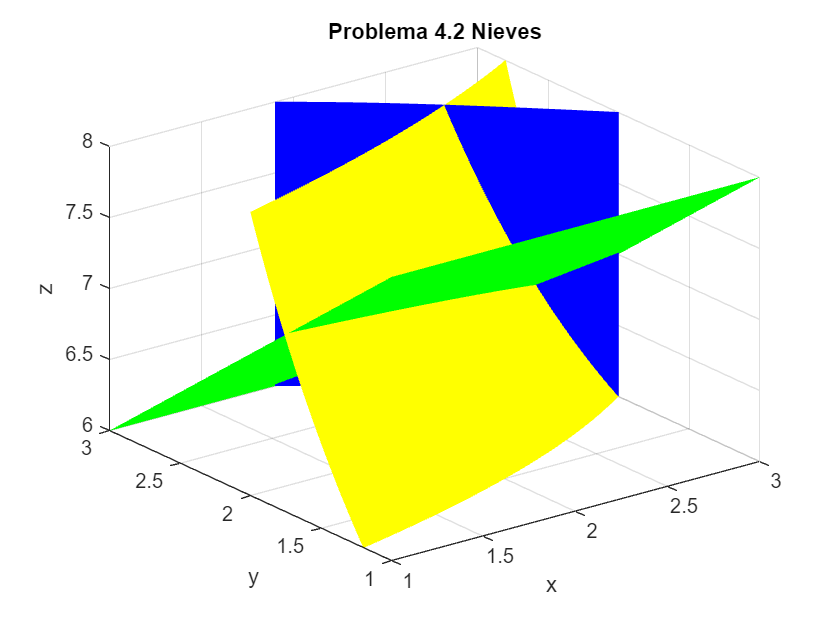

x5=3;
Ecu1=@(x,y,z)x.*y+z.*(4-y)-18;
Ecu2=@(x,y,z)y+x5+z-12;
Ecu3=@(x,y,z)x+log(y./(4-y))-3;

fimplicit3(Ecu1,[1 3 1 3 6 8],'facecolor','y','EdgeColor','none');
hold on
fimplicit3(Ecu2,[1 3 1 3 6 8],'facecolor','g','EdgeColor','none');
fimplicit3(Ecu3,[1 3 1 3 6 8],'facecolor','b','EdgeColor','none');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 4.2 Nieves')

syms x1 x2 x6;

eq1=x1*x2+x6*(4-x2)-18;
eq2=x2+x5+x6-12;
eq3=x1+log(x2/(4-x2))-3;

F_42=[eq1 eq2 eq3];
X0=[2 2 6];

[E_42,Sol_42,err_42]=Newton_Multivariable(F_42,X0,10,1e-6)

E_42 = 'La aproximacion esta dentro de la tolerancia indicada'

Sol_42 =     2.7491
    2.2496
    6.7504


err_42 = 1.0542e-07

A partir de haber determinado $x_1 ,x_2 \;y\;x_6$ podemos resolver la ecuación 5 para obtener $x_4$

x4=4-Sol_42(2);
x4

x4 = 1.7504

Las soluciones aproximadas son:


$$\begin{array}{l}
x_1 =2\ldotp 749059386418606\\
x_2 =2\ldotp 249632017562125\\
x_3 =1\ldotp 000000000000000\\
x_4 =1\ldotp 750367982437875\\
x_5 =3\ldotp 000000000000000\\
x_6 =6\ldotp 750367982437875
\end{array}$$


## Problema 4.3 Libro Nieves

Resuelva el siguiente sistema


$$\begin{array}{l}
e_1 :x_1 x_3 -x_4 \;\;\;\;\;\;\;\;\;\;\;\;=1\\
e_2 :x_2^2 x_3^2 +x_4 \;\;\;\;\;\;\;\;\;\;\;=17\\
e_3 :x_1 +x_2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=6\\
e_4 :\textrm{Ln}\left(x_3 x_4^2 \right)+x_3 x_4^2 =1
\end{array}$$


De la ecuación 3 podemos despejar $x_1$para sustituir en la ecuación, de esta forma obtenemos:


$$e_3 :x_1 +x_2 =6\cdots x_1 =6-x_2$$


Sustituyendo y resolviendo:


$$\begin{array}{l}
e_1 :\left(6-x_2 \right)x_3 -x_4 \;=1\\
e_2 :x_2^2 x_3^2 +x_4 \;\;\;\;\;\;\;\;\;\;\;=17\\
e_4 :\textrm{Ln}\left(x_3 x_4^2 \right)+x_3 x_4^2 =1
\end{array}$$


Gráfica de las 3 acuaciones:

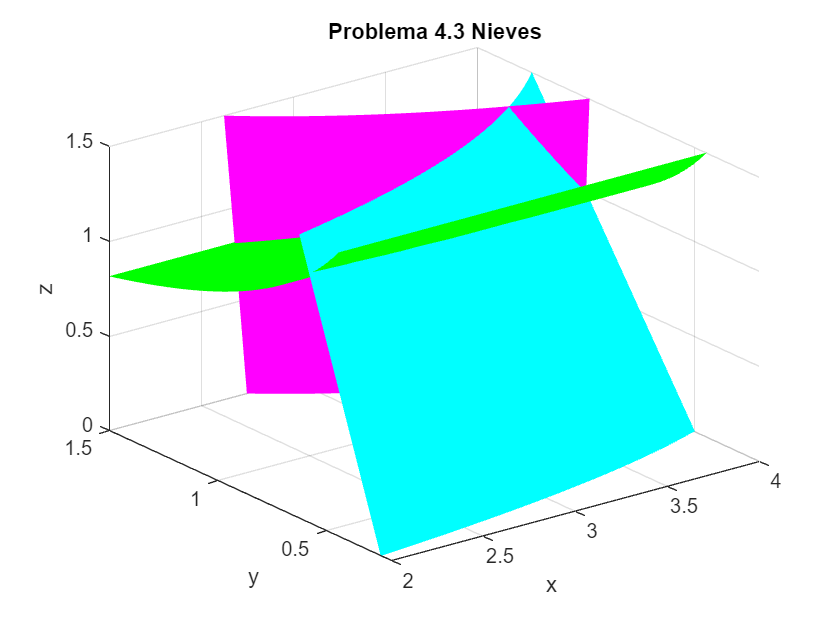

Ec1=@(x,y,z)(6-x).*y-z-1;
Ec2=@(x,y,z)(x.^2).*(y.^2)+z-17;
Ecu3=@(x,y,z)log(y.*(z.^2))+y.*(z.^2)-1;

fimplicit3(Ec1,[2 4 0 1.5 0 1.5],'facecolor','c','EdgeColor','none');
hold on
fimplicit3(Ec2,[2 4 0 1.5 0 1.5],'facecolor','m','EdgeColor','none');
fimplicit3(Ecu3,[2 4 0 1.5 0 1.5],'facecolor','g','EdgeColor','none');
hold off
xlabel('x');
ylabel('y');
zlabel('z');
title('Problema 4.3 Nieves')


syms x2 x3 x4;

eq1=(6-x2)*x3-x4-1;
eq2=(x2^2)*(x3^2)+x4-17;
eq4=log(x3*(x4^2))+x3*(x4^2)-1;

F_42=[eq1 eq2 eq4];
X0=[1 1 1];

[E,X1,err]=Newton_Multivariable(F_42,X0,15,1e-6)

E = 'La aproximacion esta dentro de la tolerancia indicada'

X1 =      4
     1
     1


err = 1.0125e-11

x1=6-X1(1)

x1 = 2

Las respectivas soluciones al sisema de ecuaciones no lineales son:


$$\begin{array}{l}
x_1 =2\\
x_2 =4\\
x_3 =1\\
x_4 =1
\end{array}$$
